train_dataset = trainingAosta;
test_dataset = testingAosta;
name = 'aosta';

train_dataset_numeric = train_dataset(:, vartype('numeric')); % Select numeric columns
train_dataset_numeric.valid_at = train_dataset.valid_at; % Add the 'valid_at' column back


test_dataset_numeric = test_dataset(:, vartype('numeric')); % Select numeric columns
test_dataset_numeric.valid_at = test_dataset.valid_at; % Add the 'valid_at' column back


train_dataset_numeric = fillmissing(train_dataset_numeric,'linear');
test_dataset_numeric = fillmissing(test_dataset_numeric,'linear');

train_dataset_numeric.sensor_id = train_dataset.sensor_id; % Add the 'sensor_id' column back
test_dataset_numeric.sensor_id = test_dataset.sensor_id; % Add the 'sensor_id' column back

train_dataset = train_dataset_numeric;
test_dataset = test_dataset_numeric;


train_dataset(train_dataset.pm2p5_x > 500, :) = [];
train_dataset(train_dataset.pm2p5_y > 500, :) = [];

test_dataset(test_dataset.pm2p5_x > 500, :) = [];
test_dataset(test_dataset.pm2p5_y > 500, :) = [];
train_dataset.month = month(train_dataset.valid_at);
test_dataset.month = month(test_dataset.valid_at);

input_features = {'pm2p5_x'; 'relative_humidity'; 'temperature'; 'pressure'};

% input_features_num_mf = [3, 3, 3, 3, 2, 3, 3, 3];
input_features_num_mf = [2, 6, 2, 2];
% input_features_num_mf = [2, 6, 2, 2, 2, 3, 3, 3];

maxK = length(input_features);

% Assuming you have input_features, table1, and table2

% Initialize an empty table to store the rows with minimum values
minRowsTable = table();
maxRowsTable = table();

% Iterate over each feature
for i = 1:numel(input_features)
    % Get the column index for the current feature
    featureIndex = find(strcmp(test_dataset.Properties.VariableNames, input_features{i}));
    
    % Find the row index with the minimum value for the current feature
    [~, minRowIndex] = min(test_dataset.(featureIndex));
    [~, maxRowIndex] = max(test_dataset.(featureIndex));

    % Extract the row with the minimum value for the current feature
    minRow = test_dataset(minRowIndex, :);
    maxRow = test_dataset(maxRowIndex, :);

    % Append the extracted row to minRowsTable
    minRowsTable = [minRowsTable; minRow];
    maxRowsTable = [maxRowsTable; maxRow];

    % Remove the extracted row from table2
    test_dataset(minRowIndex, :) = [];
    test_dataset(maxRowIndex, :) = [];
end

% Append the rows with minimum values to table1
train_dataset = [train_dataset; minRowsTable];
train_dataset = [train_dataset; maxRowsTable];

% Extract data from tables
data1 = table2array(train_dataset(:,input_features));
data2 = table2array(test_dataset(:,input_features));

% Concatenate data from both tables
all_data = [data1; data2];

% Perform min-max normalization
min_vals = min(all_data);
max_vals = max(all_data);

normalized_data1 = (data1 - min_vals) ./ (max_vals - min_vals);
normalized_data2 = (data2 - min_vals) ./ (max_vals - min_vals);

% Convert normalized data back to tables
normalized_table1 = array2table(normalized_data1, 'VariableNames', train_dataset(:,input_features).Properties.VariableNames);
normalized_table2 = array2table(normalized_data2, 'VariableNames', test_dataset(:,input_features).Properties.VariableNames);

train_dataset.pm2p5_x_original = train_dataset.pm2p5_x;
test_dataset.pm2p5_x_original = test_dataset.pm2p5_x;

% Replace normalized data columns in original tables
for i = 1:size(data1, 2)
    train_dataset.(train_dataset(:,input_features).Properties.VariableNames{i}) = normalized_data1(:, i);
end

for i = 1:size(data2, 2)
    test_dataset.(test_dataset(:,input_features).Properties.VariableNames{i}) = normalized_data2(:, i);
end


%complete_train_table = train_dataset(:,{'valid_at'; 'sensor_id'; 'pm1'; 'pm2p5_x'; 'pm4'; 'pm10'; 'relative_humidity'; 'temperature'; 'wind_speed'; 'pressure'; 'pm2p5_y'; 'pm2p5_x_original'});
%complete_test_table = test_dataset(:,{'valid_at'; 'sensor_id'; 'pm1'; 'pm2p5_x'; 'pm4'; 'pm10'; 'relative_humidity'; 'temperature'; 'wind_speed'; 'pressure'; 'pm2p5_y'; 'pm2p5_x_original'});

complete_train_table = train_dataset(:,{'valid_at'; 'sensor_id'; 'pm2p5_x'; 'relative_humidity'; 'temperature'; 'pressure'; 'pm2p5_y'; 'pm2p5_x_original'});
complete_test_table = test_dataset(:,{'valid_at'; 'sensor_id'; 'pm2p5_x'; 'relative_humidity'; 'temperature'; 'pressure'; 'pm2p5_y'; 'pm2p5_x_original'});


% Define the specific combinations
specified_combinations =  {
    %["pm2p5_x"],
    %["pm1", "pm2p5_x", "pm4", "pm10"],
    %["pm2p5_x", "relative_humidity"],
    %["pm1", "pm2p5_x", "pm4", "pm10", "relative_humidity"],
    %["pm2p5_x", "pm10", "relative_humidity"],
    %["pm2p5_x", "relative_humidity", "temperature"],
    %["pm2p5_x",  "pm10", "relative_humidity", "temperature"],
    ["pm2p5_x", "relative_humidity", "temperature", "pressure"],
    %["pm2p5_x", "pm10", "relative_humidity", "temperature", "pressure"],
    %["pm2p5_x", "relative_humidity", "temperature", "wind_speed"],
    %["pm2p5_x", "relative_humidity", "temperature", "pressure", "wind_speed"],
    %["pm2p5_x", "pm10", "relative_humidity", "temperature", "pressure", "wind_speed"]
};


% Generate and display all combinations for different values of k
for i = 1:size(specified_combinations, 1)
    currentCombination = specified_combinations{i};
    
    currentCombination_mf = input_features_num_mf(ismember(input_features, currentCombination));
    display(currentCombination_mf);
     % Perform something for combinations containing pm2p5_X
    disp('-------------------------------');
    disp(currentCombination);

    % options = genfisOptions('SubtractiveClustering');
    options = genfisOptions('GridPartition');
    options.InputMembershipFunctionType = 'trimf';
    options.NumMembershipFunctions = currentCombination_mf;

      % Assign names for inputs and output
    for j = 1:numel(currentCombination)
        outputFIS.Inputs(j).Name = currentCombination(j);
    end
    outputFIS.Outputs(1).Name = "pm2p5_y";

    % Give the FIS a descriptive name
    outputFIS.Name = "FIS_" + strjoin(currentCombination, "_");

   

    outputFIS = fitFuzzySystem(complete_train_table(:,currentCombination), complete_train_table(:,{'pm2p5_y'}), options);
    
    outputFIS
    disp('Train');
    evalFuzzySystem(outputFIS, complete_train_table, currentCombination);
    disp('Test');
    [test_results, complete_table] = evalFuzzySystem(outputFIS, complete_test_table, currentCombination);
    % save(outputFIS);
end

currentCombination_mf =      2     6     2     2


-------------------------------


    "pm2p5_x"    "relative_humidity"    "temperature"    "pressure"




ANFIS info:
	Number of nodes: 127
	Number of linear parameters: 240
	Number of nonlinear parameters: 36
	Total number of parameters: 276
	Number of training data pairs: 4552
	Number of checking data pairs: 0
	Number of fuzzy rules: 48


Start training ANFIS ...

1 	 2.65387
2 	 2.64596
3 	 2.64188
4 	 2.63975
Step size increases to 0.011000 after epoch 5.
5 	 2.63782
6 	 2.63614
7 	 2.63512
8 	 2.63366
Step size increases to 0.012100 after epoch 9.
9 	 2.63205
10 	 2.63124
11 	 2.62841
12 	 2.62907
13 	 2.62478
14 	 2.62375
15 	 2.62335
Step size increases to 0.013310 after epoch 16.
16 	 2.62283
17 	 2.62289
18 	 2.62301
19 	 2.62063
20 	 2.62045
21 	 2.61958
Step size increases to 0.014641 after epoch 22.
22 	 2.61832
23 	 2.61863
24 	 2.61832
25 	 2.61852
Step size decreases to 0.013177 after epoch 26.
26 	 2.61813
27 	 2.61848
28 	 2.61709
29 	 2.61815
Step size decreases to 0.011859 after epoch 30.
30 	 2.61674
31 	 2.61791
32 	 2.61599
33 	 2.61696
Step size decreases to 0.01067

outputFIS =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×4 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×48 fisrule]

	See 'getTunableSettings' method for parameter optimization.


outputFIS =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×4 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×48 fisrule]

	See 'getTunableSettings' method for parameter optimization.


Train


    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2433"      0.9173    1.6567    6.6506    2.5789
    "-2432"     0.92802    1.6968    7.0504    2.6553
    "all"       0.92232    1.6736    6.8194    2.6114



Test


    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2433"     0.87433    1.9826    9.8179    3.1334
    "-2432"     0.86375    2.1217    11.706    3.4215
    "all"       0.86961    2.0413    10.615     3.258



% writetable(complete_table,"matlab_" + name + "_full.csv","Delimiter",",");

test_results

test_results = 3×5 table
    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2433"     0.87433    1.9826    9.8179    3.1334
    "-2432"     0.86375    2.1217    11.706    3.4215
    "all"       0.86961    2.0413    10.615     3.258


showrule(outputFIS)

ans = 48×124 char array
    '1. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf1) and (input4 is in4mf1) then (output is out1mf1) (1)  '
    '2. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf1) and (input4 is in4mf2) then (output is out1mf2) (1)  '
    '3. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf2) and (input4 is in4mf1) then (output is out1mf3) (1)  '
    '4. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf2) and (input4 is in4mf2) then (output is out1mf4) (1)  '
    '5. If (input1 is in1mf1) and (input2 is in2mf2) and (input3 is in3mf1) and (input4 is in4mf1) then (output is out1mf5) (1)  '
    '6. If (input1 is in1mf1) and (input2 is in2mf2) and (input3 is in3mf1) and (input4 is in4mf2) then (output is out1mf6) (1)  '
    '7. If (input1 is in1mf1) and (input2 is in2mf2) and (input3 is in3mf2) and (input4 is in4mf1) then (output is out1mf7) (1)  '
    '8. If (input1 is in1mf1) and (input2 is in2mf2) and (i

% Descriptive MF labels per input feature
mf_labels_map = containers.Map;
mf_labels_map("pm2p5_x") = {"low", "high"};
mf_labels_map("relative_humidity") = {"very_low", "low", "medium", "high", "very_high", "saturated"};
mf_labels_map("temperature") = {"low", "high"};
mf_labels_map("pressure") = {"low", "high"};
% output_labels = {"low", "medium", "high"};  % Adjust if needed based on actual MF count

% Rename inputs and their MFs
for j = 1:numel(currentCombination)
    var_name = currentCombination(j);
    outputFIS.Inputs(j).Name = var_name;
    labels = mf_labels_map(var_name);
    for k = 1:numel(outputFIS.Inputs(j).MembershipFunctions)
        outputFIS.Inputs(j).MembershipFunctions(k).Name = labels{k};
    end
end

% Rename output and its MFs (if fuzzy output)
% outputFIS.Outputs(1).Name = "pm2p5_y";
% for k = 1:numel(outputFIS.Outputs(1).MembershipFunctions)
%     outputFIS.Outputs(1).MembershipFunctions(k).Name = output_labels{k};
% end


% Initialize counters for rule usage
numRules = length(outputFIS.Rules);

ruleUsageCounter = zeros(1, numRules);

% Loop through the learning dataset to analyze rule usage
numSamples = size(complete_train_table, 1);
for i = 1:numSamples
    % Extract input features for the current sample
    x_i = complete_train_table(i, currentCombination);

    % Evaluate rule activations
    ruleActivation = zeros(1, numRules);
    for r = 1:numRules
        % Calculate antecedent membership values for each rule
        antecedentValues = zeros(1, length(outputFIS.Rules(r).Antecedent));
        for j = 1:length(outputFIS.Rules(r).Antecedent)
            mfIndex = outputFIS.Rules(r).Antecedent(j);
            if mfIndex > 0 && mfIndex <= length(outputFIS.Inputs(j).MembershipFunctions)
                % Evaluate membership function for each input
                x_i_numeric = table2array(x_i);
                antecedentValues(j) = evalmf(outputFIS.Inputs(j).MembershipFunctions(mfIndex), x_i_numeric(j));
            else
                antecedentValues(j) = 0;  % Invalid membership function index, set value to 0
            end
        end
        % Calculate rule activation as the minimum of antecedent values
        ruleActivation(r) = min(antecedentValues);
    end

    % % Find the rule with maximum activation
    % [maxActivation, maxRuleIdx] = max(ruleActivation);
    
    ruleActivationIdx = find(ruleActivation > 0);
    % Increment usage counter for the most activated rule
    ruleUsageCounter(ruleActivationIdx) = ruleUsageCounter(ruleActivationIdx) + 1;

end

% Normalize rule usage counts by dividing by total number of samples
ruleUsageFrequency = ruleUsageCounter / numSamples;

% Display detailed rule usage analysis
disp('Rule Usage Frequency Analysis:');

Rule Usage Frequency Analysis:



for r = 1:numRules
    fprintf('Rule %d: %.2f%% (Activation Count: %d)\n', ...
        r, ruleUsageFrequency(r) * 100, ruleUsageCounter(r));
end

Rule 1: 13.64% (Activation Count: 621)
Rule 2: 13.75% (Activation Count: 626)
Rule 3: 13.64% (Activation Count: 621)
Rule 4: 13.75% (Activation Count: 626)
Rule 5: 34.09% (Activation Count: 1552)
Rule 6: 34.47% (Activation Count: 1569)
Rule 7: 34.01% (Activation Count: 1548)
Rule 8: 34.38% (Activation Count: 1565)
Rule 9: 46.99% (Activation Count: 2139)
Rule 10: 47.63% (Activation Count: 2168)
Rule 11: 46.90% (Activation Count: 2135)
Rule 12: 47.54% (Activation Count: 2164)
Rule 13: 48.46% (Activation Count: 2206)
Rule 14: 48.92% (Activation Count: 2227)
Rule 15: 48.44% (Activation Count: 2205)
Rule 16: 48.90% (Activation Count: 2226)
Rule 17: 39.10% (Activation Count: 1780)
Rule 18: 39.19% (Activation Count: 1784)
Rule 19: 39.10% (Activation Count: 1780)
Rule 20: 39.19% (Activation Count: 1784)
Rule 21: 15.05% (Activation Count: 685)
Rule 22: 15.05% (Activation Count: 685)
Rule 23: 15.05% (Activation Count: 685)
Rule 24: 15.05% (Activation Count: 685)
Rule 25: 13.62% (Activation Count

% Initialize counters for rule usage
numRules = length(outputFIS.Rules);

ruleUsageCounter = zeros(1, numRules);

% Loop through the learning dataset to analyze rule usage
numSamples = size(complete_train_table, 1);
for i = 1:numSamples
    % Extract input features for the current sample
    x_i = complete_train_table(i, currentCombination);

    % Evaluate rule activations
    ruleActivation = zeros(1, numRules);
    for r = 1:numRules
        % Calculate antecedent membership values for each rule
        antecedentValues = zeros(1, length(outputFIS.Rules(r).Antecedent));
        for j = 1:length(outputFIS.Rules(r).Antecedent)
            mfIndex = outputFIS.Rules(r).Antecedent(j);
            if mfIndex > 0 && mfIndex <= length(outputFIS.Inputs(j).MembershipFunctions)
                % Evaluate membership function for each input
                x_i_numeric = table2array(x_i);
                antecedentValues(j) = evalmf(outputFIS.Inputs(j).MembershipFunctions(mfIndex), x_i_numeric(j));
            else
                antecedentValues(j) = 0;  % Invalid membership function index, set value to 0
            end
        end
        % Calculate rule activation as the minimum of antecedent values
        ruleActivation(r) = min(antecedentValues);
    end

    % % Find the rule with maximum activation
    % [maxActivation, maxRuleIdx] = max(ruleActivation);
    
    ruleActivationIdx = find(ruleActivation > 0);
    % Increment usage counter for the most activated rule
    ruleUsageCounter(ruleActivationIdx) = ruleUsageCounter(ruleActivationIdx) + ruleActivation(ruleActivationIdx);

end

% Normalize rule usage counts by dividing by total number of samples
ruleUsageFrequency = ruleUsageCounter / numSamples;

% Display detailed rule usage analysis
disp('Rule Usage Frequency Analysis:');

Rule Usage Frequency Analysis:



for r = 1:numRules
    fprintf('Rule %d: %.2f%% (Activation Count: %d)\n', ...
        r, ruleUsageFrequency(r) * 100, ruleUsageCounter(r));
end

Rule 1: 0.47% (Activation Count: 2.161006e+01)
Rule 2: 1.71% (Activation Count: 7.769445e+01)
Rule 3: 0.57% (Activation Count: 2.592718e+01)
Rule 4: 2.13% (Activation Count: 9.679295e+01)
Rule 5: 1.80% (Activation Count: 8.179986e+01)
Rule 6: 6.43% (Activation Count: 2.925624e+02)
Rule 7: 2.12% (Activation Count: 9.646798e+01)
Rule 8: 7.01% (Activation Count: 3.193000e+02)
Rule 9: 2.81% (Activation Count: 1.281296e+02)
Rule 10: 8.40% (Activation Count: 3.823396e+02)
Rule 11: 2.52% (Activation Count: 1.145474e+02)
Rule 12: 7.07% (Activation Count: 3.219835e+02)
Rule 13: 3.67% (Activation Count: 1.670040e+02)
Rule 14: 8.52% (Activation Count: 3.879397e+02)
Rule 15: 2.66% (Activation Count: 1.210896e+02)
Rule 16: 6.45% (Activation Count: 2.937647e+02)
Rule 17: 4.37% (Activation Count: 1.989821e+02)
Rule 18: 6.42% (Activation Count: 2.922896e+02)
Rule 19: 2.54% (Activation Count: 1.154663e+02)
Rule 20: 4.15% (Activation Count: 1.887068e+02)
Rule 21: 2.55% (Activation Count: 1.161195e+02)
R

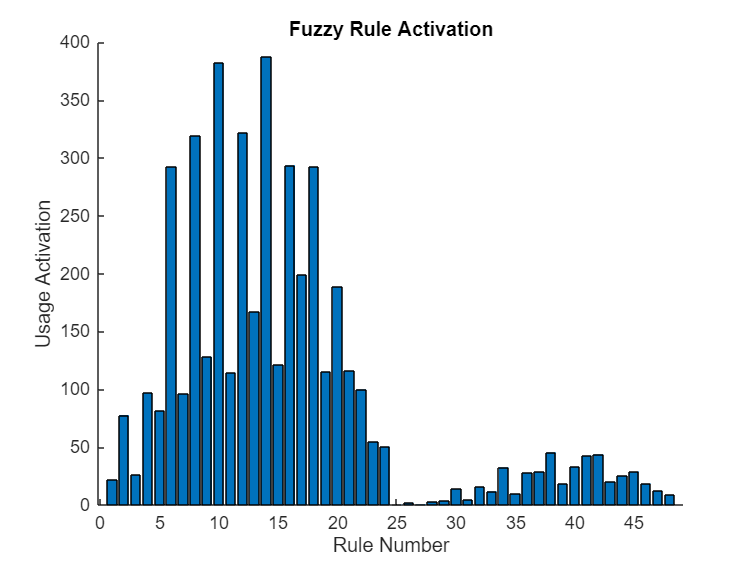

% Optional: Visualize rule usage distribution
close all;
figure;
hold on;

bar(ruleUsageCounter);
hold off;
title('Fuzzy Rule Activation');
xlabel('Rule Number');
ylabel('Usage Activation');


% bar(ruleUsageCounter);
% hold off;
% title('Fuzzy Rule Usage Counter');
% xlabel('Rule Number');
% ylabel('Usage Counter');

drawnow;
pause;

% Sort rules by frequency
[sortedFrequencies, sortedIndices] = sort(ruleUsageCounter, 'descend');
sortedIndices

sortedIndices =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48    31    29    28    26    27    25


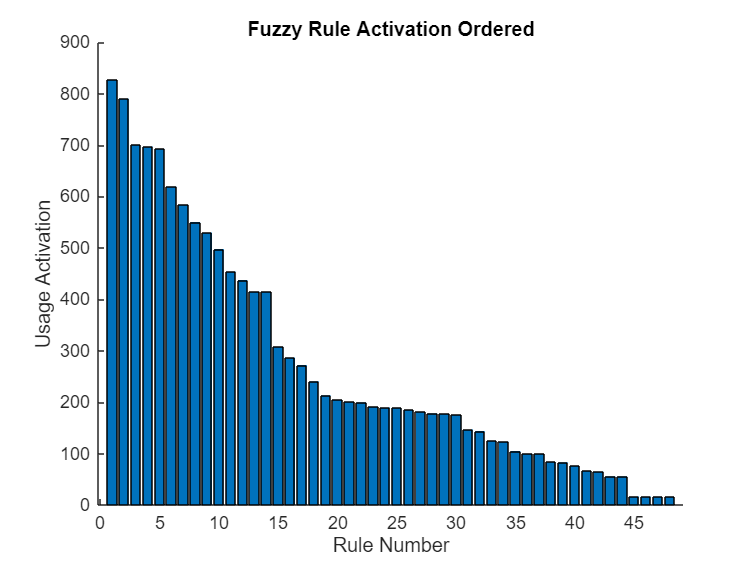

% Optional: Visualize rule usage distribution
close all;
figure;
hold on;

bar(sortedFrequencies);
hold off;
title('Fuzzy Rule Activation Ordered');
xlabel('Rule Number');
ylabel('Usage Activation');

drawnow;
pause;

% bar(sortedFrequencies);
% xticklabels(arrayfun(@num2str, sortedIndices, 'UniformOutput', false));
% 
% hold off;
% title('Fuzzy Rule Usage Counter Ordered');
% xlabel('Rule Number');
% ylabel('Usage Counter');


drawnow;
pause;


% Suppress specific warning about no rules firing
warning('off','all')

% Initialize arrays to store R^2 values
r2_train = zeros(1, numRules-1);
r2_test = zeros(1, numRules-1);

mae_train = zeros(1, numRules-1);
mae_test = zeros(1, numRules-1);

% Iteratively reduce rules and evaluate the model
for iter = 1:numRules-1
    % Keep only the top rules
    selectedRulesIdx = sortedIndices(1:end-iter+1);
    display(selectedRulesIdx)
    reducedFIS = outputFIS;
    reducedFIS.Rules = outputFIS.Rules(selectedRulesIdx);

    if length(selectedRulesIdx) ~= 48
        display(length(reducedFIS.Output.MembershipFunctions));
        reducedFIS.Output.MembershipFunctions = outputFIS.Output.MembershipFunctions(selectedRulesIdx);
        display(length(reducedFIS.Output.MembershipFunctions));
    end

    % display(reducedFIS.Rules);
    % Evaluate the model again
    disp(['Iteration ', num2str(iter), ': Evaluating with ', num2str(length(selectedRulesIdx)), ' rules']);
    % evalFuzzySystem(reducedFIS, complete_train_table, currentCombination);
    % evalFuzzySystem(reducedFIS, complete_test_table, currentCombination);
    result_train = evalFuzzySystem(reducedFIS, complete_train_table, currentCombination);
    r2_train(iter) = table2array(result_train(height(result_train),2));
    mae_train(iter) = table2array(result_train(height(result_train),3));

    result_test = evalFuzzySystem(reducedFIS, complete_test_table, currentCombination);
    r2_test(iter) = table2array(result_test(height(result_test),2));
    mae_test(iter) = table2array(result_test(height(result_test),3));
end

selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48    31    29    28    26    27    25


Iteration 1: Evaluating with 48 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18835    110.15    21410    146.32
    "-2432"     0.18561    124.79    26230    161.96
    "all"       0.18571    116.33    23445    153.12



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18588     109.7    21522     146.7
    "-2432"     0.16681    123.77    25760     160.5
    "all"       0.17601    115.64    23310    152.68



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48    31    29    28    26    27


    48



    47



Iteration 2: Evaluating with 47 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18835    110.16    21410    146.32
    "-2432"     0.18562    124.79    26230    161.96
    "all"       0.18572    116.34    23445    153.12



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18587     109.7    21522     146.7
    "-2432"     0.16681    123.77    25760     160.5
    "all"         0.176    115.64    23311    152.68



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48    31    29    28    26


    48



    46



Iteration 3: Evaluating with 46 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1881    110.12    21408    146.31
    "-2432"     0.18537    124.77    26228    161.95
    "all"       0.18547    116.31    23443    153.11



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18565    109.66    21518    146.69
    "-2432"     0.16667    123.74    25757    160.49
    "all"       0.17582     115.6    23307    152.67



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48    31    29    28


    48



    45



Iteration 4: Evaluating with 45 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18829    110.16    21412    146.33
    "-2432"     0.18564     124.8    26234    161.97
    "all"       0.18569    116.34    23448    153.13



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18577    109.69    21522     146.7
    "-2432"     0.16682    123.77    25761     160.5
    "all"       0.17595    115.63    23310    152.68



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48    31    29


    48



    44



Iteration 5: Evaluating with 44 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18836    110.18    21414    146.34
    "-2432"     0.18574    124.83    26238    161.98
    "all"       0.18578    116.36    23451    153.14



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18581    109.71    21524    146.71
    "-2432"     0.16684     123.8    25764    160.51
    "all"       0.17598    115.66    23313    152.69



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48    31


    48



    43



Iteration 6: Evaluating with 43 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"       0.194    109.21    21196    145.59
    "-2432"     0.19268    123.91    26014    161.29
    "all"       0.19204    115.41    23230    152.42



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18602    108.83    21320    146.01
    "-2432"     0.16791    122.94    25539    159.81
    "all"       0.17657    114.78    23100    151.99



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35    48


    48



    42



Iteration 7: Evaluating with 42 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.19136    110.38    21392    146.26
    "-2432"     0.18902    124.76    26188    161.83
    "all"       0.18895    116.45    23417    153.03



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18578     110.1    21517    146.69
    "-2432"     0.16644    123.71    25701    160.31
    "all"       0.17584    115.84    23282    152.59



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33    35


    48



    41



Iteration 8: Evaluating with 41 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.19102    110.34    21388    146.25
    "-2432"     0.18897    124.69    26182    161.81
    "all"       0.18875     116.4    23412    153.01



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1849    110.08    21514    146.67
    "-2432"     0.16637    123.64    25695     160.3
    "all"       0.17533     115.8    23278    152.57



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47    33


    48



    40



Iteration 9: Evaluating with 40 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1897    110.43    21444    146.44
    "-2432"      0.1884    124.83    26251    162.02
    "all"       0.18778    116.51    23474    153.21



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18446    110.14    21559    146.83
    "-2432"     0.16534    123.77    25767    160.52
    "all"       0.17462    115.89    23335    152.76



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30    47


    48



    39



Iteration 10: Evaluating with 39 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.22251    108.64    20853     144.4
    "-2432"     0.22511    122.59    25480    159.62
    "all"       0.22243    114.53    22806    151.02



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.20722    108.44    20996     144.9
    "-2432"     0.20036    121.28    24927    157.88
    "all"       0.20292    113.86    22655    150.51



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32    30


    48



    38



Iteration 11: Evaluating with 38 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.22621    109.94    20986    144.87
    "-2432"     0.22717    124.17    25648    160.15
    "all"       0.22541    115.95    22955    151.51



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.21161    109.54    21109    145.29
    "-2432"     0.20335    122.64    25067    158.32
    "all"        0.2067    115.07    22779    150.93



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39    32


    48



    37



Iteration 12: Evaluating with 37 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.20315    112.79    21774    147.56
    "-2432"     0.19882    127.51    26604    163.11
    "all"        0.1998       119    23813    154.32



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.20668    112.15    21873     147.9
    "-2432"     0.19725     125.4    25936    161.05
    "all"       0.20124    117.74    23587    153.58



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46    39


    48



    36



Iteration 13: Evaluating with 36 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.19073    114.89    22321     149.4
    "-2432"     0.18316    129.76    27246    165.06
    "all"       0.18586    121.17    24400    156.21



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.20315    114.02    22331    149.43
    "-2432"     0.19333     126.9    26375    162.41
    "all"       0.19759    119.46    24037    155.04



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43    46


    48



    35



Iteration 14: Evaluating with 35 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14235    117.68    23003    151.67
    "-2432"     0.12815    133.29    28176    167.86
    "all"       0.13439    124.27    25188    158.71



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16223    116.98    23038    151.78
    "-2432"     0.14993    130.67    27272    165.14
    "all"       0.15553    122.76    24825    157.56



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1    43


    48



    34



Iteration 15: Evaluating with 34 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14259    117.73    23011    151.69
    "-2432"     0.12845    133.34    28185    167.89
    "all"       0.13466    124.32    25196    158.73



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16256    117.03    23047    151.81
    "-2432"     0.15048    130.72    27282    165.17
    "all"       0.15597    122.81    24834    157.59



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44     1


    48



    33



Iteration 16: Evaluating with 33 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16183    119.23    23168    152.21
    "-2432"     0.14714    135.26    28458     168.7
    "all"       0.15369       126    25402    159.38



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17576    118.89    23223    152.39
    "-2432"     0.16028    132.88    27543    165.96
    "all"       0.16768    124.79    25046    158.26



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3    44


    48



    32



Iteration 17: Evaluating with 32 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16353    119.51    23207    152.34
    "-2432"     0.14901    135.59    28507    168.84
    "all"       0.15546     126.3    25445    159.51



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17761     119.2    23269    152.54
    "-2432"     0.16227    133.22    27597    166.12
    "all"       0.16958    125.12    25095    158.41



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36     3


    48



    31



Iteration 18: Evaluating with 31 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17182    120.47    23320    152.71
    "-2432"     0.15528    136.59    28664     169.3
    "all"        0.1628    127.28    25577    159.93



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18427    120.43    23392    152.94
    "-2432"     0.16507    134.36    27727    166.51
    "all"       0.17451    126.31    25221    158.81



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37    36


    48



    30



Iteration 19: Evaluating with 30 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17162    120.68    23346    152.79
    "-2432"     0.15512     136.8    28691    169.39
    "all"       0.16262    127.48    25603    160.01



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18427    120.64    23424    153.05
    "-2432"     0.16512    134.59    27759    166.61
    "all"       0.17454    126.53    25253    158.91



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45    37


    48



    29



Iteration 20: Evaluating with 29 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14311    123.06    24222    155.63
    "-2432"     0.12371    139.57    29801    172.63
    "all"       0.13277    130.03    26577    163.03



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15697    123.13    24313    155.93
    "-2432"      0.1344    137.39    28881    169.94
    "all"       0.14572    129.15    26240    161.99



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34    45


    48



    28



Iteration 21: Evaluating with 28 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.2226    119.66    23416    153.02
    "-2432"     0.21714    134.78    28635    169.22
    "all"       0.21887    126.05    25619    160.06



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.21903    119.38    23424    153.05
    "-2432"     0.20307    132.19    27687    166.39
    "all"       0.21082    124.79    25222    158.82



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40    34


    48



    27



Iteration 22: Evaluating with 27 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.2212    118.95    23300    152.64
    "-2432"     0.21618    133.93    28490    168.79
    "all"       0.21765    125.28    25492    159.66



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.21734    118.72    23320    152.71
    "-2432"     0.20148    131.41    27559    166.01
    "all"       0.20916    124.08    25109    158.46



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41    40


    48



    26



Iteration 23: Evaluating with 26 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18871    121.09    24356    156.06
    "-2432"     0.17739    136.87    29965     173.1
    "all"       0.18217    127.75    26724    163.48



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18985    120.92    24405    156.22
    "-2432"     0.17301    134.23    28988    170.26
    "all"        0.1812    126.54    26338    162.29



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42    41


    48



    25



Iteration 24: Evaluating with 25 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18829    121.53    24551    156.69
    "-2432"      0.1771    137.47    30216    173.83
    "all"        0.1818    128.26    26943    164.14



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18572    121.38    24613    156.89
    "-2432"     0.17065     134.8    29244    171.01
    "all"       0.17787    127.04    26567    162.99



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38    42


    48



    24



Iteration 25: Evaluating with 24 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16893     119.7    24315    155.93
    "-2432"     0.15418    134.74    29801    172.63
    "all"       0.16065    126.05    26631    163.19



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17226    119.44    24386    156.16
    "-2432"      0.1571     132.1    28907    170.02
    "all"       0.16428    124.78    26293    162.15



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24    38


    48



    23



Iteration 26: Evaluating with 23 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14589    118.58    24249    155.72
    "-2432"     0.12951    133.38    29700    172.34
    "all"       0.13677    124.83    26550    162.94



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15634    117.89    24308    155.91
    "-2432"       0.145    130.41    28828    169.79
    "all"       0.14999    123.17    26215    161.91



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23    24


    48



    22



Iteration 27: Evaluating with 22 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.087411    121.62    25325    159.14
    "-2432"     0.059621    137.42    31174    176.56
    "all"       0.073017    128.29    27794    166.72



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.082048     121.7    25760     160.5
    "-2432"     0.054684    135.52    30714    175.26
    "all"       0.068579    127.53    27851    166.89



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2    23


    48



    21



Iteration 28: Evaluating with 21 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.088033    123.41    25506    159.71
    "-2432"     0.057911    139.04    31343    177.04
    "all"       0.072588    130.01    27971    167.24



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.087562    123.86    25968    161.15
    "-2432"     0.054079    137.09    30873    175.71
    "all"       0.071382    129.44    28038    167.44



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5     2


    48



    20



Iteration 29: Evaluating with 20 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.086755    121.28    25305    159.08
    "-2432"     0.058203    136.74    31137    176.46
    "all"       0.071983     127.8    27768    166.64



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.086738    121.73    25766    160.52
    "-2432"     0.054814    135.22    30708    175.24
    "all"       0.071218    127.43    27851    166.89



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7     5


    48



    19



Iteration 30: Evaluating with 19 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.097252    123.21    25611    160.03
    "-2432"     0.070273    139.13    31518    177.53
    "all"       0.083133    129.93    28105    167.65



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.097723    123.55    26069    161.46
    "-2432"     0.067269    137.36    31080    176.29
    "all"       0.082802    129.38    28183    167.88



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4     7


    48



    18



Iteration 31: Evaluating with 18 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.11033    127.32    27157    164.79
    "-2432"     0.085199    143.91    33412    182.79
    "all"       0.097007    134.33    29798    172.62



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.11381    127.47    27460    165.71
    "-2432"     0.085075    141.69    32741    180.94
    "all"       0.099609    133.47    29688     172.3



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22     4


    48



    17



Iteration 32: Evaluating with 17 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.12051    131.22    28458    168.69
    "-2432"     0.093723    147.39    34733    186.37
    "all"        0.10648    138.05    31108    176.37



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1286    131.71    28792    169.68
    "-2432"     0.09675    145.01    33970    184.31
    "all"       0.11311    137.32    30977       176



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11    22


    48



    16



Iteration 33: Evaluating with 16 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1688    141.39    30993    176.05
    "-2432"     0.14443    158.51    37583    193.86
    "all"       0.15568    148.62    33776    183.78



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17942    141.81    31318    176.97
    "-2432"     0.14553    155.48    36678    191.51
    "all"       0.16295    147.58    33579    183.25



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19    11


    48



    15



Iteration 34: Evaluating with 15 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17164    138.48    30814    175.54
    "-2432"     0.14935    155.25    37388    193.36
    "all"       0.15935    145.56    33590    183.28



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17576    138.56    31119     176.4
    "-2432"     0.14582    152.27    36483       191
    "all"       0.16098    144.35    33382    182.71



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21    19


    48



    14



Iteration 35: Evaluating with 14 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1684    146.26    34073    184.59
    "-2432"     0.14153    162.24    40839    202.09
    "all"       0.15422    153.01    36930    192.17



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17599    146.12    34174    184.86
    "-2432"     0.13959     159.2    39788    199.47
    "all"       0.15846    151.64    36543    191.16



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15    21


    48



    13



Iteration 36: Evaluating with 13 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16464    147.09    34253    185.08
    "-2432"     0.14085    163.31    41053    202.62
    "all"       0.15182    153.94    37124    192.68



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17676    146.62    34324    185.27
    "-2432"     0.14342    160.37    39988    199.97
    "all"        0.1605    152.42    36714    191.61



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9    15


    48



    12



Iteration 37: Evaluating with 12 rules


    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16399    148.88    34358    185.36
    "-2432"     0.14149    165.55    41184    202.94
    "all"       0.15167    155.92    37240    192.98



    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17803    148.27    34420    185.53
    "-2432"      0.1436    161.99    40086    200.21
    "all"       0.16125    154.06    36811    191.86



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13     9


    48



    11



Iteration 38: Evaluating with 11 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.12937    159.69    37539    193.75
    "-2432"     0.099536     175.7    44554    211.08
    "all"        0.11383    166.45    40501    201.25



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.14141    159.48    37770    194.34
    "-2432"     0.097984    174.01    43979    209.71
    "all"         0.1206    165.61    40390    200.97



selectedRulesIdx =     14    10    12     8    16     6    18    17    20    13


    48



    10



Iteration 39: Evaluating with 10 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.12587    166.34    41984     204.9
    "-2432"     0.096644    184.13    50389    224.48
    "all"        0.11054    173.85    45533    213.38



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.13759    165.27    41612    203.99
    "-2432"     0.094834    181.64    49191    221.79
    "all"        0.11691    172.18    44810    211.68



selectedRulesIdx =     14    10    12     8    16     6    18    17    20


    48



     9



Iteration 40: Evaluating with 9 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.10477    171.41    45062    212.28
    "-2432"     0.071961    191.34    54748    233.98
    "all"       0.087682    179.83    49152     221.7



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.11124    171.42    45128    212.43
    "-2432"     0.063226    190.47    54241     232.9
    "all"       0.088036    179.46    48973     221.3



selectedRulesIdx =     14    10    12     8    16     6    18    17


    48



     8



Iteration 41: Evaluating with 8 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.10348    173.85    45441    213.17
    "-2432"     0.068259    193.43    55111    234.76
    "all"       0.085312    182.12    49524    222.54



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.11415    173.68    45466    213.23
    "-2432"     0.062259    192.34    54590    233.64
    "all"       0.089277    181.55    49316    222.07



selectedRulesIdx =     14    10    12     8    16     6    18


    48



     7



Iteration 42: Evaluating with 7 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.10527    181.28    46195    214.93
    "-2432"     0.064956    201.33    55969    236.58
    "all"       0.085066    189.74    50322    224.33



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.11276    181.18    46163    214.86
    "-2432"     0.060551    200.32    55411     235.4
    "all"       0.087968    189.26    50065    223.75



selectedRulesIdx =     14    10    12     8    16     6


    48



     6



Iteration 43: Evaluating with 6 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.088909    191.36    50816    225.42
    "-2432"     0.044924    211.31    61005    246.99
    "all"       0.066805    199.78    55118    234.77



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      0.10242    188.88    50103    223.84
    "-2432"     0.058281    211.25    60513    245.99
    "all"       0.080881    198.32    54496    233.44



selectedRulesIdx =     14    10    12     8    16


    48



     5



Iteration 44: Evaluating with 5 rules


    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.065665    185.27    50433    224.57
    "-2432"     0.026858    205.63    61590    248.17
    "all"       0.045915    193.87    55144    234.83



    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.071317    182.07    49062     221.5
    "-2432"     0.031188     204.9    59923    244.79
    "all"       0.051598     191.7    53645    231.61



selectedRulesIdx =     14    10    12     8


    48



     4



Iteration 45: Evaluating with 4 rules


    SensorID        R2         MAE       MSE      RMSE 
    ________    __________    ______    _____    ______

    "-2433"     -0.0076591    242.79    83010    288.11
    "-2432"      -0.039815    254.52    91560    302.59
    "all"        -0.023087    247.74    86620    294.31



    SensorID       R2         MAE       MSE      RMSE 
    ________    _________    ______    _____    ______

    "-2433"     -0.015796    236.07    79958    282.77
    "-2432"     -0.054984    257.75    92107    303.49
    "all"       -0.034232    245.22    85084    291.69



selectedRulesIdx =     14    10    12


    48



     3



Iteration 46: Evaluating with 3 rules


    SensorID       R2         MAE         MSE         RMSE 
    ________    _________    ______    __________    ______

    "-2433"     -0.021988    243.91         90698    301.16
    "-2432"     -0.051278    258.55    1.0167e+05    318.86
    "all"       -0.036146    250.09         95332    308.76



    SensorID       R2         MAE         MSE         RMSE 
    ________    _________    ______    __________    ______

    "-2433"     -0.030494    233.64         86065    293.37
    "-2432"     -0.052858    259.38    1.0074e+05    317.39
    "all"       -0.041557     244.5         92256    303.74



selectedRulesIdx =     14    10


    48



     2



Iteration 47: Evaluating with 2 rules


    SensorID        R2          MAE         MSE         RMSE 
    ________    ___________    ______    __________    ______

    "-2433"        0.022234    391.12    2.3618e+05    485.99
    "-2432"       -0.028342    385.43    2.3448e+05    484.23
    "all"       -0.00026371    388.72    2.3546e+05    485.25



    SensorID        R2         MAE         MSE         RMSE 
    ________    __________    ______    __________    ______

    "-2433"       0.038036    383.46    2.3163e+05    481.27
    "-2432"     0.00096769    377.37    2.2355e+05    472.81
    "all"         0.022369    380.89    2.2822e+05    477.72



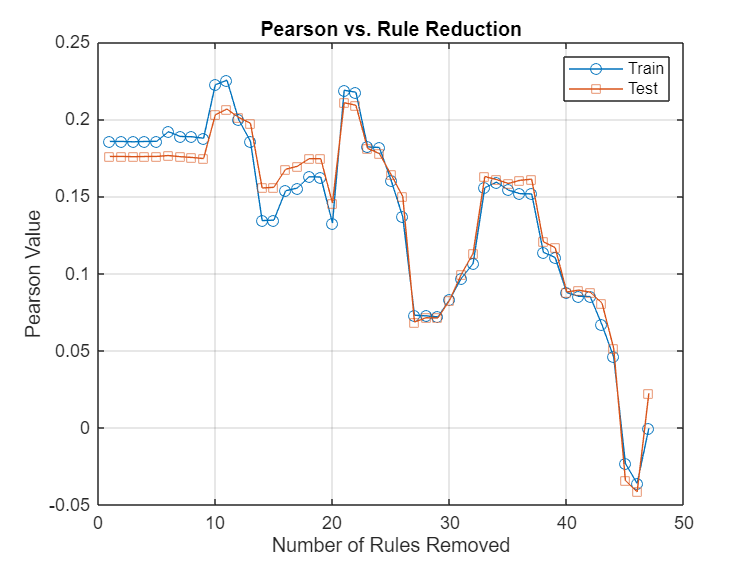

figure;
plot(1:numRules-1, r2_train, '-o', 'DisplayName', 'Train');
hold on;
plot(1:numRules-1, r2_test, '-s', 'DisplayName', 'Test');

xlabel('Number of Rules Removed');
ylabel('Pearson Value');
title('Pearson vs. Rule Reduction');

legend;
grid on;

pause;

% Plot MAE values
figure;
plot(1:numRules-1, mae_train, '-o', 'DisplayName', 'Train MAE');
hold on;
plot(1:numRules-1, mae_test, '-s', 'DisplayName', 'Test MAE');

xlabel('Number of Rules Removed');
ylabel('MAE Value');
title('MAE vs. Rule Reduction');

legend;
grid on;
pause;

% Sort rules by frequency
[sortedFrequencies, sortedIndices] = sort(ruleUsageCounter, 'descend');
sortedIndices

sortedIndices =      7     8    10    14    11     9    12     5    13     6    18    15    16    38     3    37    17    34    33     4    42    19    20    41    35    36    40    39    22    44    43    21    46    24    23     1    45     2    31    32    30    29    48    47    27    28    25    26


% Suppress specific warning about no rules firing
warning('off','all')

% Initialize arrays to store R^2 values
r2_train = zeros(1, numRules-1);
r2_test = zeros(1, numRules-1);

mae_train = zeros(1, numRules-1);
mae_test = zeros(1, numRules-1);

mse_train = zeros(1, numRules-1);
mse_test = zeros(1, numRules-1);

rmse_train = zeros(1, numRules-1);
rmse_test = zeros(1, numRules-1);
% Iteratively reduce rules and evaluate the model
for iter = 1:numRules-1
    % Keep only the top rules
    selectedRulesIdx = sortedIndices(1:end-iter+1);

    reducedFIS = outputFIS;

    x = complete_train_table(:,currentCombination);
    y = complete_train_table(:,{'pm2p5_y'});
    
    if length(selectedRulesIdx) ~= 48
        reducedFIS.Rules = reducedFIS.Rules(selectedRulesIdx);

        display(length(reducedFIS.Output.MembershipFunctions));
        reducedFIS.Output.MembershipFunctions = reducedFIS.Output.MembershipFunctions(selectedRulesIdx);
        display(length(reducedFIS.Output.MembershipFunctions));
    end

    display('Retraining...');
    % retrainedFIS = anfis([x{:,:}, y{:,:}], reducedFIS, 100);
    opt = tunefisOptions("Method","anfis");
    [in,out,rule] = getTunableSettings(reducedFIS);

    x_data = x{:,:};
    y_data = y{:,:};
    assert(size(x_data,1) == size(y_data,1), 'Input/output size mismatch');

    retrainedFIS = tunefis(reducedFIS,[in;out],x{:,:}, y{:,:},opt);

    % Evaluate the model again
    disp(['Iteration ', num2str(iter), ': Evaluating with ', num2str(length(selectedRulesIdx)), ' rules']);


    result_train = evalFuzzySystem(retrainedFIS, complete_train_table, currentCombination);
    r2_train(iter) = table2array(result_train(height(result_train),2));
    mae_train(iter) = table2array(result_train(height(result_train),3));
    mse_train(iter) = table2array(result_train(height(result_train),4));
    rmse_train(iter) = table2array(result_train(height(result_train),5));

    result_test = evalFuzzySystem(retrainedFIS, complete_test_table, currentCombination);
    r2_test(iter) = table2array(result_test(height(result_test),2));
    mae_test(iter) = table2array(result_test(height(result_test),3));
    mse_test(iter) = table2array(result_test(height(result_test),4));
    rmse_test(iter) = table2array(result_test(height(result_test),5));
end

Retraining...



ANFIS info:
	Number of nodes: 127
	Number of linear parameters: 240
	Number of nonlinear parameters: 36
	Total number of parameters: 276
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 48


Start training ANFIS ...

1 	 1.24548
2 	 1.24384
3 	 1.24491
4 	 1.24262
5 	 1.24384
Step size decreases to 0.009000 after epoch 6.
6 	 1.24196
7 	 1.24286
8 	 1.24115
9 	 1.24217
Step size decreases to 0.008100 after epoch 10.
10 	 1.24054

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.24054


Iteration 1: Evaluating with 48 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97589    0.89482    1.5389    1.2405
    "all"               0.97589    0.89482    1.5389    1.2405



        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.96476    0.96861    1.8829    1.3722
    "all"               0.96476    0.96861    1.8829    1.3722



    48



    47



Retraining...



ANFIS info:
	Number of nodes: 125
	Number of linear parameters: 235
	Number of nonlinear parameters: 36
	Total number of parameters: 271
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 47


Start training ANFIS ...

1 	 1.24546
2 	 1.24387
3 	 1.24486
4 	 1.24267
5 	 1.24389
Step size decreases to 0.009000 after epoch 6.
6 	 1.24188
7 	 1.24282
8 	 1.24109
9 	 1.24206
Step size decreases to 0.008100 after epoch 10.
10 	 1.24047

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.24047


Iteration 2: Evaluating with 47 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97589    0.89425    1.5388    1.2405
    "all"               0.97589    0.89425    1.5388    1.2405



        SensorID          R2        MAE       MSE       RMSE 
    ________________    ______    _______    ______    ______

    "Sensor Calgary"    0.9647    0.97119    1.8867    1.3736
    "all"               0.9647    0.97119    1.8867    1.3736



    48



    46



Retraining...



ANFIS info:
	Number of nodes: 123
	Number of linear parameters: 230
	Number of nonlinear parameters: 36
	Total number of parameters: 266
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 46


Start training ANFIS ...

1 	 1.24549
2 	 1.24395
3 	 1.24483
4 	 1.24277
5 	 1.24407
Step size decreases to 0.009000 after epoch 6.
6 	 1.24204
7 	 1.2432
8 	 1.24099
9 	 1.24223
Step size decreases to 0.008100 after epoch 10.
10 	 1.24039

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.24039


Iteration 3: Evaluating with 46 rules


        SensorID          R2       MAE       MSE       RMSE 
    ________________    ______    ______    ______    ______

    "Sensor Calgary"    0.9759    0.8951    1.5386    1.2404
    "all"               0.9759    0.8951    1.5386    1.2404



        SensorID          R2        MAE       MSE       RMSE 
    ________________    ______    _______    ______    ______

    "Sensor Calgary"    0.9647    0.96904    1.8863    1.3734
    "all"               0.9647    0.96904    1.8863    1.3734



    48



    45



Retraining...



ANFIS info:
	Number of nodes: 121
	Number of linear parameters: 225
	Number of nonlinear parameters: 36
	Total number of parameters: 261
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 45


Start training ANFIS ...

1 	 1.25848
2 	 1.25679
3 	 1.25765
4 	 1.25586
5 	 1.25656
Step size decreases to 0.009000 after epoch 6.
6 	 1.25554
7 	 1.25609
8 	 1.25455
9 	 1.25553
Step size decreases to 0.008100 after epoch 10.
10 	 1.25427

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.25427


Iteration 4: Evaluating with 45 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97535    0.90491    1.5732    1.2543
    "all"               0.97535    0.90491    1.5732    1.2543



        SensorID          R2         MAE       MSE      RMSE 
    ________________    _______    _______    _____    ______

    "Sensor Calgary"    0.96459    0.98244    1.892    1.3755
    "all"               0.96459    0.98244    1.892    1.3755



    48



    44



Retraining...



ANFIS info:
	Number of nodes: 119
	Number of linear parameters: 220
	Number of nonlinear parameters: 36
	Total number of parameters: 256
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 44


Start training ANFIS ...

1 	 1.28396
2 	 1.28202
3 	 1.28046
4 	 1.28051
5 	 1.27897
6 	 1.27747
7 	 1.27424
Step size increases to 0.011000 after epoch 8.
8 	 1.26871
9 	 1.26865
10 	 1.26954

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.26865


Iteration 5: Evaluating with 44 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97477    0.93009    1.6095    1.2686
    "all"               0.97477    0.93009    1.6095    1.2686



        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.96326    0.99365    1.9613    1.4005
    "all"               0.96326    0.99365    1.9613    1.4005



    48



    43



Retraining...



ANFIS info:
	Number of nodes: 117
	Number of linear parameters: 215
	Number of nonlinear parameters: 36
	Total number of parameters: 251
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 43


Start training ANFIS ...

1 	 1.28514
2 	 1.28329
3 	 1.28167
4 	 1.28228
5 	 1.2793
6 	 1.27859
7 	 1.27357
Step size increases to 0.011000 after epoch 8.
8 	 1.26934
9 	 1.26821
10 	 1.26816

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.26816


Iteration 6: Evaluating with 43 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97479    0.92967    1.6082    1.2682
    "all"               0.97479    0.92967    1.6082    1.2682



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96329    0.9931    1.9602    1.4001
    "all"               0.96329    0.9931    1.9602    1.4001



    48



    42



Retraining...



ANFIS info:
	Number of nodes: 115
	Number of linear parameters: 210
	Number of nonlinear parameters: 36
	Total number of parameters: 246
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 42


Start training ANFIS ...

1 	 1.29787
2 	 1.29507
3 	 1.29348
4 	 1.29067
Step size increases to 0.011000 after epoch 5.
5 	 1.28356
6 	 1.27796
7 	 1.27783
8 	 1.27842
9 	 1.27728
10 	 1.27805

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.27728


Iteration 7: Evaluating with 42 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97442    0.93677    1.6314    1.2773
    "all"               0.97442    0.93677    1.6314    1.2773



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96322    1.0043    1.9649    1.4017
    "all"               0.96322    1.0043    1.9649    1.4017



    48



    41



Retraining...



ANFIS info:
	Number of nodes: 113
	Number of linear parameters: 205
	Number of nonlinear parameters: 36
	Total number of parameters: 241
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 41


Start training ANFIS ...

1 	 1.30956
2 	 1.3069
3 	 1.30567
4 	 1.30128
Step size increases to 0.011000 after epoch 5.
5 	 1.2919
6 	 1.28399
7 	 1.28748
8 	 1.28554
9 	 1.28605
Step size decreases to 0.009900 after epoch 10.
10 	 1.28453

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.28399


Iteration 8: Evaluating with 41 rules


        SensorID          R2         MAE       MSE      RMSE 
    ________________    _______    _______    ______    _____

    "Sensor Calgary"    0.97415    0.94285    1.6486    1.284
    "all"               0.97415    0.94285    1.6486    1.284



        SensorID          R2       MAE       MSE      RMSE 
    ________________    ______    ______    ______    _____

    "Sensor Calgary"    0.9632    1.0038    1.9655    1.402
    "all"               0.9632    1.0038    1.9655    1.402



    48



    40



Retraining...



ANFIS info:
	Number of nodes: 111
	Number of linear parameters: 200
	Number of nonlinear parameters: 36
	Total number of parameters: 236
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 40


Start training ANFIS ...

1 	 1.32102
2 	 1.3189
3 	 1.31728
4 	 1.31678
Step size increases to 0.011000 after epoch 5.
5 	 1.31565
6 	 1.3149
7 	 1.31478
8 	 1.31344
Step size increases to 0.012100 after epoch 9.
9 	 1.31199
10 	 1.31353

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.31199


Iteration 9: Evaluating with 40 rules


        SensorID          R2        MAE       MSE      RMSE 
    ________________    _______    ______    ______    _____

    "Sensor Calgary"    0.97299    0.9505    1.7213    1.312
    "all"               0.97299    0.9505    1.7213    1.312



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96341    1.0276    1.9555    1.3984
    "all"               0.96341    1.0276    1.9555    1.3984



    48



    39



Retraining...



ANFIS info:
	Number of nodes: 109
	Number of linear parameters: 195
	Number of nonlinear parameters: 36
	Total number of parameters: 231
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 39


Start training ANFIS ...

1 	 1.33359
2 	 1.33053
3 	 1.3282
4 	 1.32747
Step size increases to 0.011000 after epoch 5.
5 	 1.32587
6 	 1.32652
7 	 1.32358
8 	 1.32358
Step size decreases to 0.009900 after epoch 9.
9 	 1.32168
10 	 1.3222

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.32168


Iteration 10: Evaluating with 39 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97259    0.96232    1.7468    1.3217
    "all"               0.97259    0.96232    1.7468    1.3217



        SensorID          R2        MAE      MSE     RMSE 
    ________________    _______    _____    _____    _____

    "Sensor Calgary"    0.96305    1.039    1.974    1.405
    "all"               0.96305    1.039    1.974    1.405



    48



    38



Retraining...



ANFIS info:
	Number of nodes: 107
	Number of linear parameters: 190
	Number of nonlinear parameters: 36
	Total number of parameters: 226
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 38


Start training ANFIS ...

1 	 1.34109
2 	 1.33797
3 	 1.336
4 	 1.33411
Step size increases to 0.011000 after epoch 5.
5 	 1.33213
6 	 1.33083
7 	 1.3301
8 	 1.32728
Step size increases to 0.012100 after epoch 9.
9 	 1.32585
10 	 1.32556

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.32556


Iteration 11: Evaluating with 38 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97242    0.96751    1.7571    1.3256
    "all"               0.97242    0.96751    1.7571    1.3256



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96283    1.0353    1.9869    1.4096
    "all"               0.96283    1.0353    1.9869    1.4096



    48



    37



Retraining...



ANFIS info:
	Number of nodes: 105
	Number of linear parameters: 185
	Number of nonlinear parameters: 36
	Total number of parameters: 221
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 37


Start training ANFIS ...

1 	 1.34448
2 	 1.34064
3 	 1.339
4 	 1.33773
Step size increases to 0.011000 after epoch 5.
5 	 1.33553
6 	 1.33549
7 	 1.33363
8 	 1.33258
Step size increases to 0.012100 after epoch 9.
9 	 1.32934
10 	 1.32965

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.32934


Iteration 12: Evaluating with 37 rules


        SensorID          R2         MAE       MSE       RMSE 
    ________________    _______    _______    ______    ______

    "Sensor Calgary"    0.97226    0.96873    1.7672    1.3293
    "all"               0.97226    0.96873    1.7672    1.3293



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96274    1.0334    1.9918    1.4113
    "all"               0.96274    1.0334    1.9918    1.4113



    48



    36



Retraining...



ANFIS info:
	Number of nodes: 103
	Number of linear parameters: 180
	Number of nonlinear parameters: 36
	Total number of parameters: 216
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 36


Start training ANFIS ...

1 	 1.34783
2 	 1.3444
3 	 1.34259
4 	 1.34141
Step size increases to 0.011000 after epoch 5.
5 	 1.3395
6 	 1.33901
7 	 1.33838
8 	 1.33708
Step size increases to 0.012100 after epoch 9.
9 	 1.33615
10 	 1.33602

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.33602


Iteration 13: Evaluating with 36 rules


        SensorID          R2         MAE       MSE     RMSE 
    ________________    _______    _______    _____    _____

    "Sensor Calgary"    0.97198    0.97404    1.785    1.336
    "all"               0.97198    0.97404    1.785    1.336



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96183    1.0532    2.0377    1.4275
    "all"               0.96183    1.0532    2.0377    1.4275



    48



    35



Retraining...



ANFIS info:
	Number of nodes: 101
	Number of linear parameters: 175
	Number of nonlinear parameters: 36
	Total number of parameters: 211
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 35


Start training ANFIS ...

1 	 1.34865
2 	 1.34499
3 	 1.34243
4 	 1.3435
5 	 1.34077
6 	 1.3412
Step size decreases to 0.009000 after epoch 7.
7 	 1.33965
8 	 1.33986
9 	 1.33787
10 	 1.33786

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.33786


Iteration 14: Evaluating with 35 rules


        SensorID          R2        MAE       MSE       RMSE 
    ________________    ______    _______    ______    ______

    "Sensor Calgary"    0.9719    0.97385    1.7899    1.3379
    "all"               0.9719    0.97385    1.7899    1.3379



        SensorID          R2        MAE       MSE      RMSE 
    ________________    _______    ______    ______    _____

    "Sensor Calgary"    0.96177    1.0435    2.0421    1.429
    "all"               0.96177    1.0435    2.0421    1.429



    48



    34



Retraining...



ANFIS info:
	Number of nodes: 99
	Number of linear parameters: 170
	Number of nonlinear parameters: 36
	Total number of parameters: 206
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 34


Start training ANFIS ...

1 	 1.3643
2 	 1.36073
3 	 1.35629
4 	 1.35365
Step size increases to 0.011000 after epoch 5.
5 	 1.35235
6 	 1.35097
7 	 1.34919
8 	 1.34765
9 	 1.34828
10 	 1.34602

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.34602


Iteration 15: Evaluating with 34 rules


        SensorID          R2         MAE       MSE      RMSE 
    ________________    _______    _______    ______    _____

    "Sensor Calgary"    0.97155    0.98689    1.8118    1.346
    "all"               0.97155    0.98689    1.8118    1.346



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96125    1.0472    2.0747    1.4404
    "all"               0.96125    1.0472    2.0747    1.4404



    48



    33



Retraining...



ANFIS info:
	Number of nodes: 97
	Number of linear parameters: 165
	Number of nonlinear parameters: 36
	Total number of parameters: 201
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 33


Start training ANFIS ...

1 	 1.39766
2 	 1.39315
3 	 1.38818
4 	 1.38673
Step size increases to 0.011000 after epoch 5.
5 	 1.38367
6 	 1.38424
7 	 1.3808
8 	 1.38143
Step size decreases to 0.009900 after epoch 9.
9 	 1.37683
10 	 1.37586

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.37586


Iteration 16: Evaluating with 33 rules


        SensorID          R2        MAE       MSE      RMSE 
    ________________    _______    ______    _____    ______

    "Sensor Calgary"    0.97026    1.0138    1.893    1.3759
    "all"               0.97026    1.0138    1.893    1.3759



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96155    1.0594    2.0552    1.4336
    "all"               0.96155    1.0594    2.0552    1.4336



    48



    32



Retraining...



ANFIS info:
	Number of nodes: 95
	Number of linear parameters: 160
	Number of nonlinear parameters: 36
	Total number of parameters: 196
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 32


Start training ANFIS ...

1 	 1.40812
2 	 1.40348
3 	 1.39481
4 	 1.39512
5 	 1.39196
6 	 1.39247
Step size decreases to 0.009000 after epoch 7.
7 	 1.38966
8 	 1.39096
9 	 1.38633
10 	 1.38691

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.38633


Iteration 17: Evaluating with 32 rules


        SensorID          R2       MAE       MSE       RMSE 
    ________________    ______    ______    ______    ______

    "Sensor Calgary"    0.9698    1.0176    1.9219    1.3863
    "all"               0.9698    1.0176    1.9219    1.3863



        SensorID          R2        MAE       MSE      RMSE 
    ________________    _______    ______    _____    ______

    "Sensor Calgary"    0.95985    1.0717    2.144    1.4643
    "all"               0.95985    1.0717    2.144    1.4643



    48



    31



Retraining...



ANFIS info:
	Number of nodes: 93
	Number of linear parameters: 155
	Number of nonlinear parameters: 36
	Total number of parameters: 191
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 31


Start training ANFIS ...

1 	 1.41664
2 	 1.41047
3 	 1.40786
4 	 1.39959
5 	 1.40226
6 	 1.39682
7 	 1.39751
Step size decreases to 0.009000 after epoch 8.
8 	 1.39419
9 	 1.39541
10 	 1.39182

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.39182


Iteration 18: Evaluating with 31 rules


        SensorID          R2        MAE      MSE       RMSE 
    ________________    _______    _____    ______    ______

    "Sensor Calgary"    0.96955    1.018    1.9372    1.3918
    "all"               0.96955    1.018    1.9372    1.3918



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96027    1.0656    2.1236    1.4573
    "all"               0.96027    1.0656    2.1236    1.4573



    48



    30



Retraining...



ANFIS info:
	Number of nodes: 91
	Number of linear parameters: 150
	Number of nonlinear parameters: 36
	Total number of parameters: 186
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 30


Start training ANFIS ...

1 	 1.42385
2 	 1.41857
3 	 1.41622
4 	 1.41577
5 	 1.41622
6 	 1.41537
7 	 1.4131
8 	 1.41399
9 	 1.41078
10 	 1.41228

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.41078


Iteration 19: Evaluating with 30 rules


        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.96871    1.0278    1.9903    1.4108
    "all"               0.96871    1.0278    1.9903    1.4108



        SensorID          R2        MAE      MSE      RMSE 
    ________________    _______    _____    ______    _____

    "Sensor Calgary"    0.95745    1.084    2.2681    1.506
    "all"               0.95745    1.084    2.2681    1.506



    48



    29



Retraining...



ANFIS info:
	Number of nodes: 89
	Number of linear parameters: 145
	Number of nonlinear parameters: 36
	Total number of parameters: 181
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 29


Start training ANFIS ...

1 	 1.43454
2 	 1.43146
3 	 1.43293
4 	 1.42672
5 	 1.42372
6 	 1.42314
Step size increases to 0.011000 after epoch 7.
7 	 1.41846
8 	 1.42443
9 	 1.41737
10 	 1.41422

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.41422


Iteration 20: Evaluating with 29 rules


        SensorID          R2        MAE      MSE     RMSE 
    ________________    _______    ______    ___    ______

    "Sensor Calgary"    0.96855    1.0344     2     1.4142
    "all"               0.96855    1.0344     2     1.4142



        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.95786    1.0988    2.2463    1.4988
    "all"               0.95786    1.0988    2.2463    1.4988



    48



    28



Retraining...



ANFIS info:
	Number of nodes: 87
	Number of linear parameters: 140
	Number of nonlinear parameters: 36
	Total number of parameters: 176
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 28


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 21: Evaluating with 28 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    27



Retraining...



ANFIS info:
	Number of nodes: 85
	Number of linear parameters: 135
	Number of nonlinear parameters: 36
	Total number of parameters: 171
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 27


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 22: Evaluating with 27 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    26



Retraining...



ANFIS info:
	Number of nodes: 83
	Number of linear parameters: 130
	Number of nonlinear parameters: 36
	Total number of parameters: 166
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 26


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 23: Evaluating with 26 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    25



Retraining...



ANFIS info:
	Number of nodes: 81
	Number of linear parameters: 125
	Number of nonlinear parameters: 36
	Total number of parameters: 161
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 25


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 24: Evaluating with 25 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    24



Retraining...



ANFIS info:
	Number of nodes: 79
	Number of linear parameters: 120
	Number of nonlinear parameters: 36
	Total number of parameters: 156
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 24


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 25: Evaluating with 24 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    23



Retraining...



ANFIS info:
	Number of nodes: 77
	Number of linear parameters: 115
	Number of nonlinear parameters: 36
	Total number of parameters: 151
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 23


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 26: Evaluating with 23 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    22



Retraining...



ANFIS info:
	Number of nodes: 75
	Number of linear parameters: 110
	Number of nonlinear parameters: 36
	Total number of parameters: 146
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 22


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 27: Evaluating with 22 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    21



Retraining...



ANFIS info:
	Number of nodes: 73
	Number of linear parameters: 105
	Number of nonlinear parameters: 36
	Total number of parameters: 141
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 21


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 28: Evaluating with 21 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    20



Retraining...



ANFIS info:
	Number of nodes: 71
	Number of linear parameters: 100
	Number of nonlinear parameters: 36
	Total number of parameters: 136
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 20


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 29: Evaluating with 20 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    19



Retraining...



ANFIS info:
	Number of nodes: 69
	Number of linear parameters: 95
	Number of nonlinear parameters: 36
	Total number of parameters: 131
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 19


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 30: Evaluating with 19 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    18



Retraining...



ANFIS info:
	Number of nodes: 67
	Number of linear parameters: 90
	Number of nonlinear parameters: 36
	Total number of parameters: 126
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 18


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 31: Evaluating with 18 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    17



Retraining...



ANFIS info:
	Number of nodes: 65
	Number of linear parameters: 85
	Number of nonlinear parameters: 36
	Total number of parameters: 121
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 17


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 32: Evaluating with 17 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    16



Retraining...



ANFIS info:
	Number of nodes: 63
	Number of linear parameters: 80
	Number of nonlinear parameters: 36
	Total number of parameters: 116
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 16


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 33: Evaluating with 16 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    15



Retraining...



ANFIS info:
	Number of nodes: 61
	Number of linear parameters: 75
	Number of nonlinear parameters: 36
	Total number of parameters: 111
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 15


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 34: Evaluating with 15 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    14



Retraining...



ANFIS info:
	Number of nodes: 59
	Number of linear parameters: 70
	Number of nonlinear parameters: 36
	Total number of parameters: 106
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 14


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 35: Evaluating with 14 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    13



Retraining...



ANFIS info:
	Number of nodes: 57
	Number of linear parameters: 65
	Number of nonlinear parameters: 36
	Total number of parameters: 101
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 13


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 36: Evaluating with 13 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    12



Retraining...



ANFIS info:
	Number of nodes: 55
	Number of linear parameters: 60
	Number of nonlinear parameters: 36
	Total number of parameters: 96
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 12


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 37: Evaluating with 12 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    11



Retraining...



ANFIS info:
	Number of nodes: 53
	Number of linear parameters: 55
	Number of nonlinear parameters: 36
	Total number of parameters: 91
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 11


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 38: Evaluating with 11 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



    10



Retraining...



ANFIS info:
	Number of nodes: 51
	Number of linear parameters: 50
	Number of nonlinear parameters: 36
	Total number of parameters: 86
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 10


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 39: Evaluating with 10 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     9



Retraining...



ANFIS info:
	Number of nodes: 49
	Number of linear parameters: 45
	Number of nonlinear parameters: 36
	Total number of parameters: 81
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 9


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 40: Evaluating with 9 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     8



Retraining...



ANFIS info:
	Number of nodes: 47
	Number of linear parameters: 40
	Number of nonlinear parameters: 36
	Total number of parameters: 76
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 8


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 41: Evaluating with 8 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     7



Retraining...



ANFIS info:
	Number of nodes: 45
	Number of linear parameters: 35
	Number of nonlinear parameters: 36
	Total number of parameters: 71
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 42: Evaluating with 7 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     6



Retraining...



ANFIS info:
	Number of nodes: 43
	Number of linear parameters: 30
	Number of nonlinear parameters: 36
	Total number of parameters: 66
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 43: Evaluating with 6 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     5



Retraining...



ANFIS info:
	Number of nodes: 41
	Number of linear parameters: 25
	Number of nonlinear parameters: 36
	Total number of parameters: 61
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 44: Evaluating with 5 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     4



Retraining...



ANFIS info:
	Number of nodes: 39
	Number of linear parameters: 20
	Number of nonlinear parameters: 36
	Total number of parameters: 56
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 4


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 45: Evaluating with 4 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     3



Retraining...



ANFIS info:
	Number of nodes: 37
	Number of linear parameters: 15
	Number of nonlinear parameters: 36
	Total number of parameters: 51
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 3


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 46: Evaluating with 3 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



    48



     2



Retraining...



ANFIS info:
	Number of nodes: 35
	Number of linear parameters: 10
	Number of nonlinear parameters: 36
	Total number of parameters: 46
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 2


Start training ANFIS ...

1 	 NaN
2 	 0

Error goal (0) reached. ANFIS training completed at epoch 2.

Minimal training RMSE = 0


Iteration 47: Evaluating with 2 rules


        SensorID        R2      MAE      MSE     RMSE 
    ________________    ___    ______    ___    ______

    "Sensor Calgary"    NaN    13.231    195    13.964
    "all"               NaN    13.231    195    13.964



        SensorID        R2      MAE       MSE       RMSE 
    ________________    ___    ______    ______    ______

    "Sensor Calgary"    NaN    13.534    201.75    14.204
    "all"               NaN    13.534    201.75    14.204



r2_train
r2_test
mae_train
mae_test
mse_train
mse_test
rmse_train
rmse_test



figure;
plot(1:numRules-1, r2_train, '-o', 'DisplayName', 'Train');
hold on;
plot(1:numRules-1, r2_test, '-s', 'DisplayName', 'Test');

xlabel('Number of Rules Removed');
ylabel('Pearson Value');
title('Pearson vs. Rule Reduction');

legend;
grid on;
pause;

zoom = 31;
figure;
plot(1:zoom, r2_train(1:zoom), '-o', 'DisplayName', 'Train');
hold on;
plot(1:zoom, r2_test(1:zoom), '-s', 'DisplayName', 'Test');

xlabel('Number of Rules Removed');
ylabel('Pearson Value');
title('Pearson vs. Rule Reduction (Zoom)');

legend;
grid on;
pause;

% Plot R^2 values
figure;
plot(1:numRules-1, mae_train, '-o', 'DisplayName', 'Train MAE');
hold on;
plot(1:numRules-1, mae_test, '-s', 'DisplayName', 'Test MAE');

xlabel('Number of Rules Removed');
ylabel('MAE Value');
title('MAE vs. Rule Reduction');

legend;
grid on;
pause;

% Plot R^2 values
zoom = 31;
figure;
plot(1:zoom, mae_train(1:zoom), '-o', 'DisplayName', 'Train MAE');
hold on;
plot(1:zoom, mae_test(1:zoom), '-s', 'DisplayName', 'Test MAE');

xlabel('Number of Rules Removed');
ylabel('MAE Value');
title('MAE vs. Rule Reduction (Zoom)');

legend;
grid on;
pause;

% Suppress specific warning about no rules firing
warning('off','all')



% Keep only the top rules
rules_befor_drop = 29

rules_befor_drop = 29

selectedRulesIdx = sortedIndices(1:rules_befor_drop);

reducedFIS = outputFIS;

x = complete_train_table(:,currentCombination);
y = complete_train_table(:,{'pm2p5_y'});

if length(selectedRulesIdx) ~= 48
    reducedFIS.Rules = reducedFIS.Rules(selectedRulesIdx);

    display(length(reducedFIS.Output.MembershipFunctions));
    reducedFIS.Output.MembershipFunctions = reducedFIS.Output.MembershipFunctions(selectedRulesIdx);
    display(length(reducedFIS.Output.MembershipFunctions));
end

    48



    29




display('Retraining...');

Retraining...


% retrainedFIS = anfis([x{:,:}, y{:,:}], reducedFIS, 100);
opt = tunefisOptions("Method","anfis");
[in,out,rule] = getTunableSettings(reducedFIS);

x_data = x{:,:};
y_data = y{:,:};
assert(size(x_data,1) == size(y_data,1), 'Input/output size mismatch');

retrainedFIS = tunefis(reducedFIS,[in;out],x{:,:}, y{:,:},opt);


ANFIS info:
	Number of nodes: 89
	Number of linear parameters: 145
	Number of nonlinear parameters: 36
	Total number of parameters: 181
	Number of training data pairs: 2276
	Number of checking data pairs: 0
	Number of fuzzy rules: 29


Start training ANFIS ...

1 	 1.43454
2 	 1.43146
3 	 1.43293
4 	 1.42672
5 	 1.42372
6 	 1.42314
Step size increases to 0.011000 after epoch 7.
7 	 1.41846
8 	 1.42443
9 	 1.41737
10 	 1.41422

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 1.41422




result_train = evalFuzzySystem(retrainedFIS, complete_train_table, currentCombination);

        SensorID          R2        MAE      MSE     RMSE 
    ________________    _______    ______    ___    ______

    "Sensor Calgary"    0.96855    1.0344     2     1.4142
    "all"               0.96855    1.0344     2     1.4142



r2_train = table2array(result_train(height(result_train),2));
mae_train = table2array(result_train(height(result_train),3));
mse_train = table2array(result_train(height(result_train),4));
rmse_train = table2array(result_train(height(result_train),5));

[result_test, complete_table] = evalFuzzySystem(retrainedFIS, complete_test_table, currentCombination);

        SensorID          R2        MAE       MSE       RMSE 
    ________________    _______    ______    ______    ______

    "Sensor Calgary"    0.95786    1.0988    2.2463    1.4988
    "all"               0.95786    1.0988    2.2463    1.4988




writetable(complete_table,"matlab_" + name + "_" + rules_befor_drop + "_rules.csv","Delimiter",",");

r2_test = table2array(result_test(height(result_test),2));
mae_test = table2array(result_test(height(result_test),3));
mse_test = table2array(result_test(height(result_test),4));
rmse_test = table2array(result_test(height(result_test),5));
